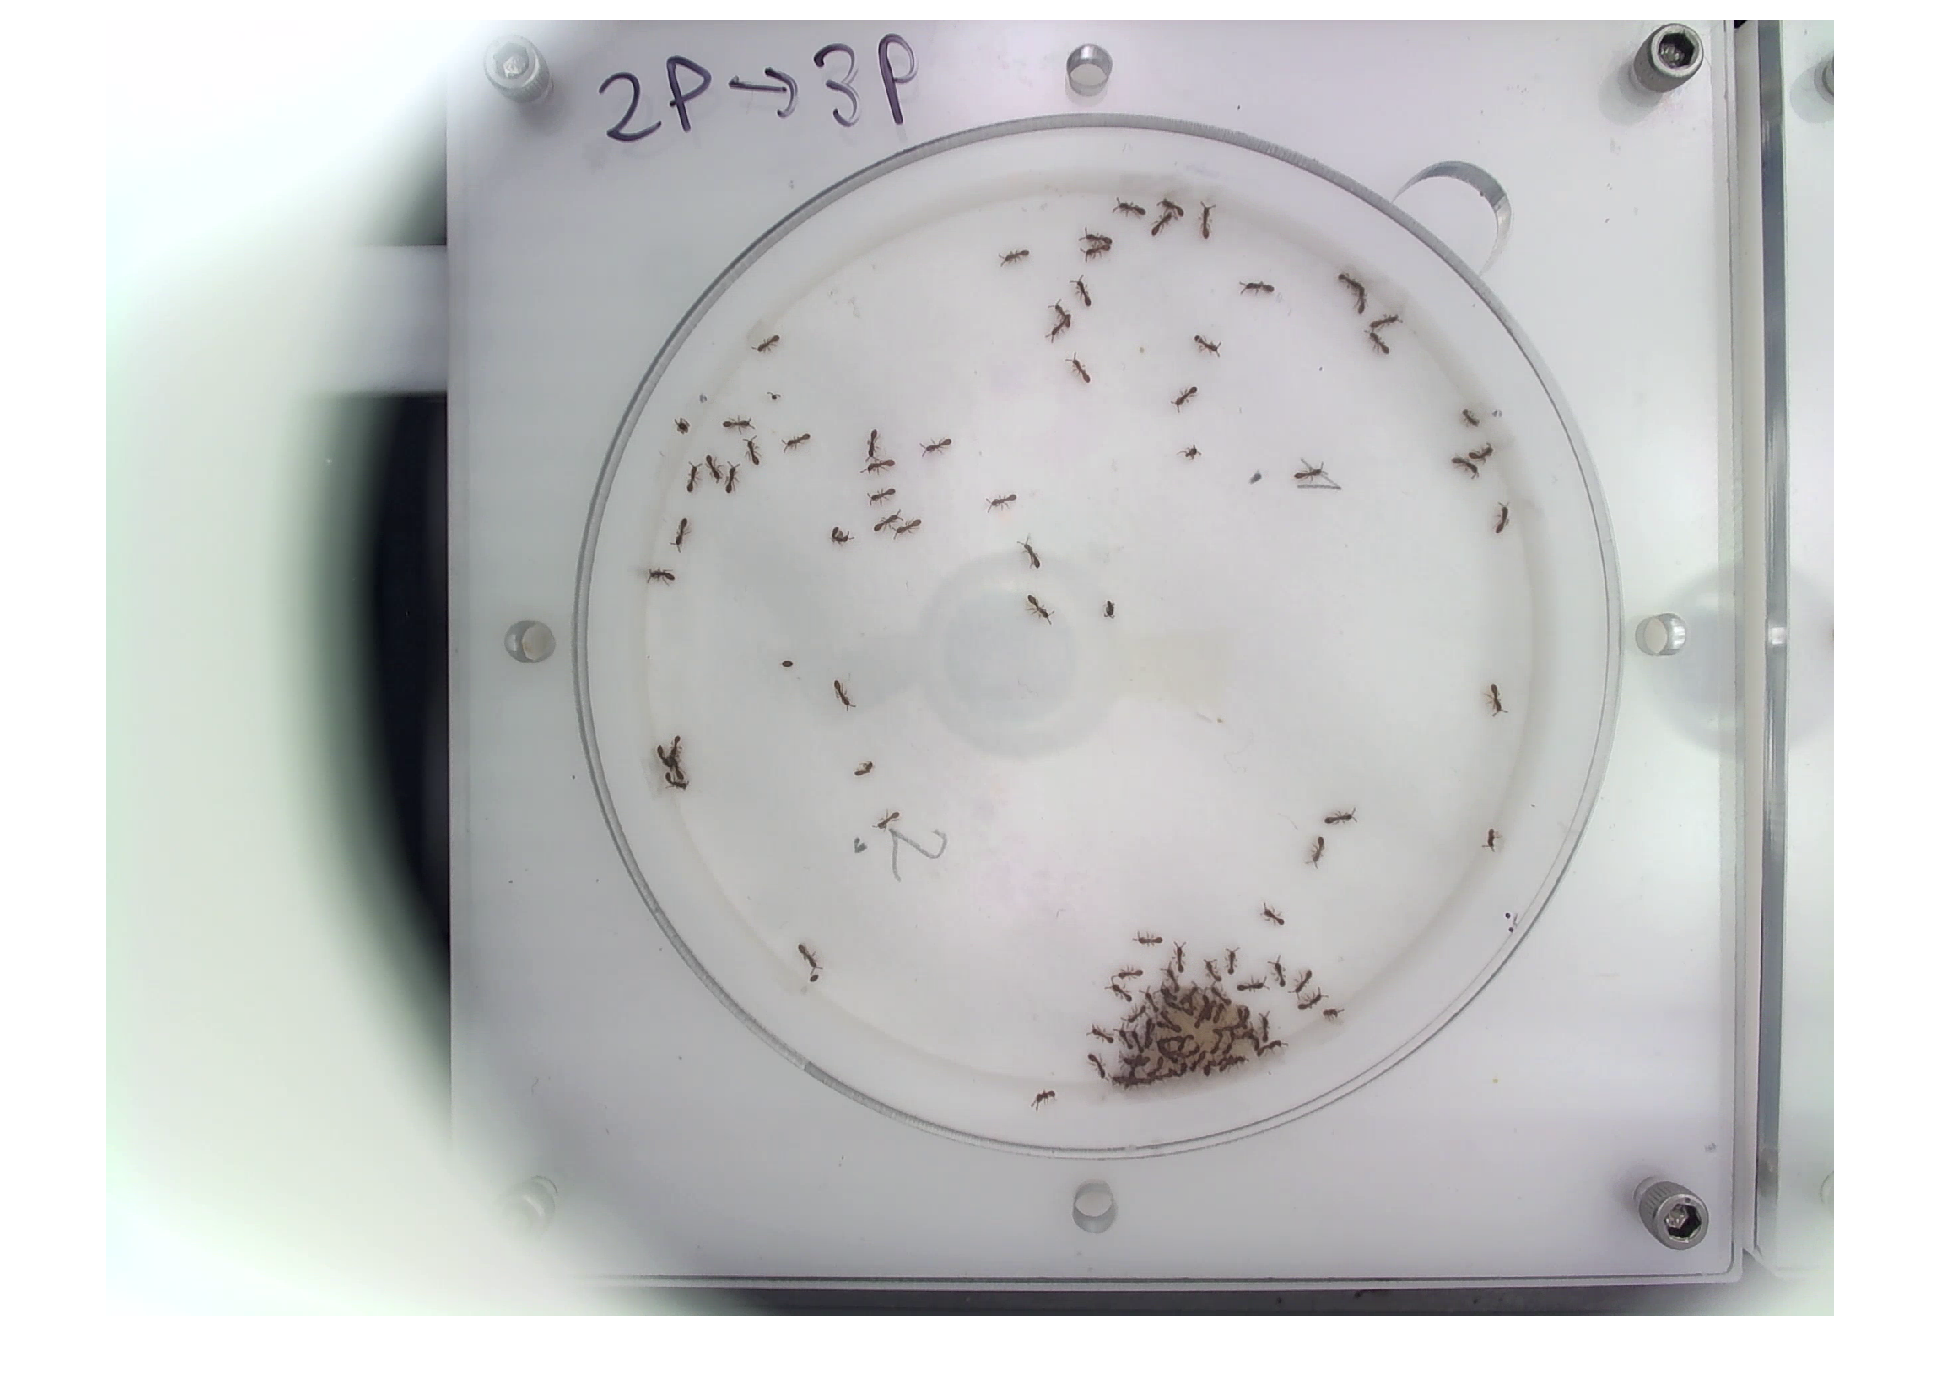

%-------------------------------------------------------------------------%
% cLusterTrax program by Dennis Octavio Melendez 6.9.2023
%-------------------------------------------------------------------------%
% Must install the following: 'trimage.m', 'drawroi.m', 'blackroi.mat', and
% 'findcluster.m' into your MATLAB directory.
%-------------------------------------------------------------------------%

% To load your experimental workspace: 
% cd(strcat(exp_folder,"\"));
%      load('workspace.mat')
% To load specific variables:
%     load('workspace.mat', 'cluster_heatmap', 'Currtable')
% To prevent overwriting current variables:
%     Experiment1_heatmap = load('workspace.mat', 'cluster_heatmap');
%     or
%     Heatmaps(i) = load('workspace.mat', 'cluster_heatmap');


%%%%%PYTHON SCRIPT FIRST


% exp_folder is the path to your images "C:<full_path>\<to_image_folder>"
%for mac use /
exp_folder = "/path_to_folder_with_timelapse_images";
% This creates the variable 'basename', the "name" of your images folder
[parent, basename, ~] = fileparts(exp_folder);
%restoredefaultpath

% Creates the variable 'D' with the contents of your images folder
D = dir(exp_folder);
% Removes any information from hidden files
D = D(~[D.isdir] & ~startsWith({D.name}, '.'));
% Store the filenames into a cell array
filenames = {D.name};
% The next 3 lines are to ensure that the filenames are in ascending order
%%%%%HAD TO CHANGE NAME to Timelapse_frame
numericValues = cellfun(@(x) sscanf(x, 'Timelapse_frame%d.png'), filenames);
% Sort the numeric values and get the sorted indices
[~, sortedIndices] = sort(numericValues, 'ascend');
% Sort D according to the sorted indices
D = D(sortedIndices);


% Change your working directory to the path in 'exp_folder'
cd(exp_folder)

% These three variables will be passed to the trimage.m function
frame = imread(D(1).name); % Read the image 1 and store it in 'frame'
square = 1; % Do you want to trim your image to a perfect square? [1, 0]
edge_buffer = 25; % Pixel buffer for human error in image point selection

% Pass different variables to trimage.m depending on whether you've
% already determined the dimensions of your trimmed image previously
if ~exist('length_x', 'var') || ~exist('length_y', 'var')
    [trimmed_image, corner_x, corner_y, length_x, length_y] = trimage(frame, square, edge_buffer);
else
    [trimmed_image, corner_x, corner_y] = trimage(frame, square, edge_buffer, 1);
end

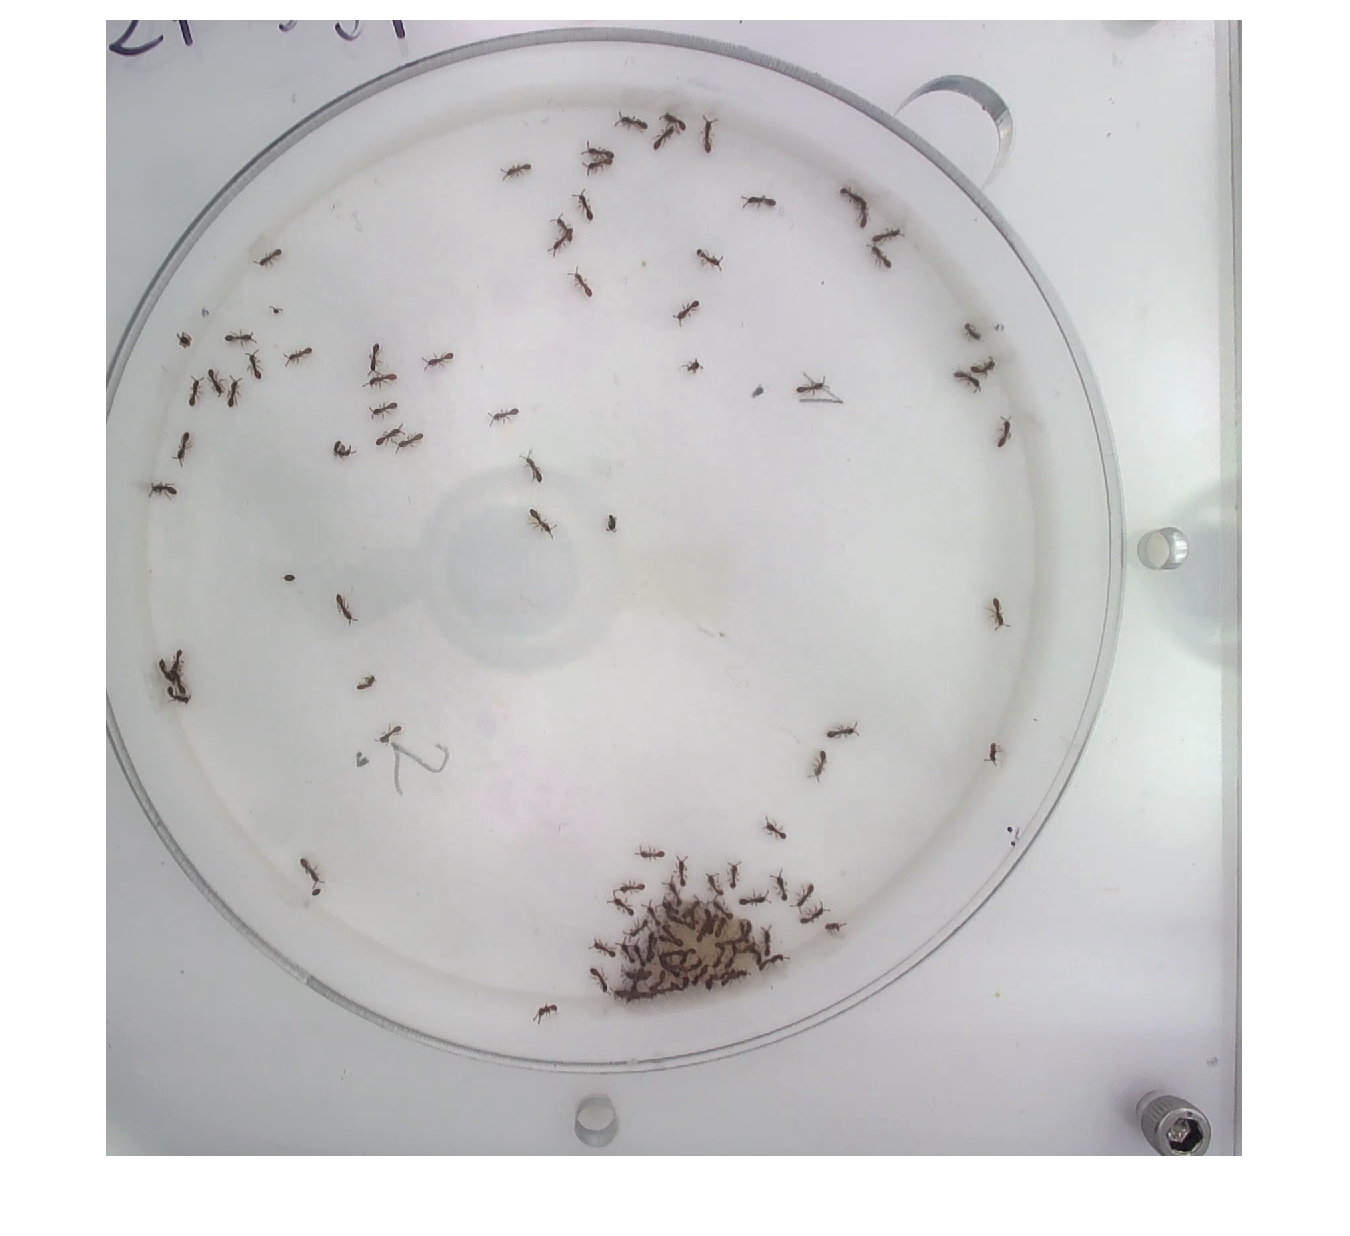

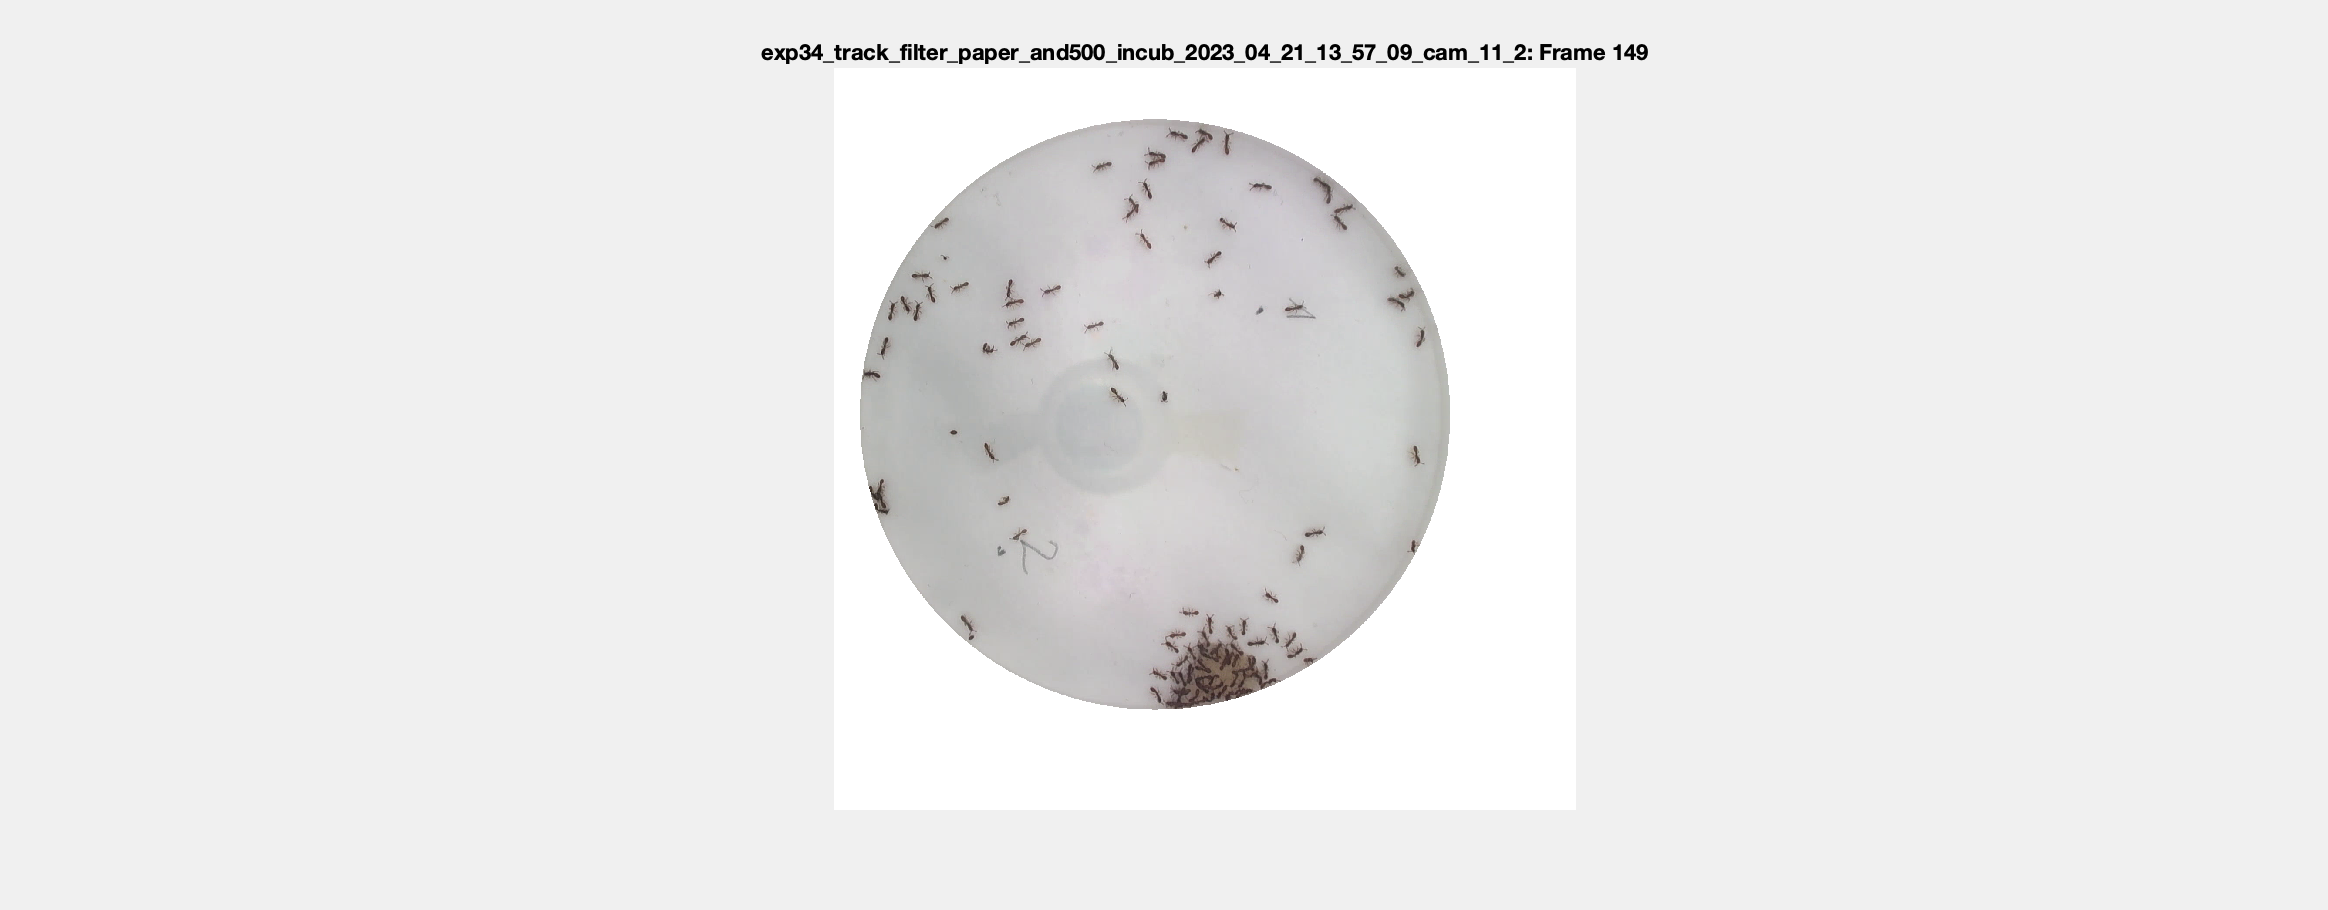

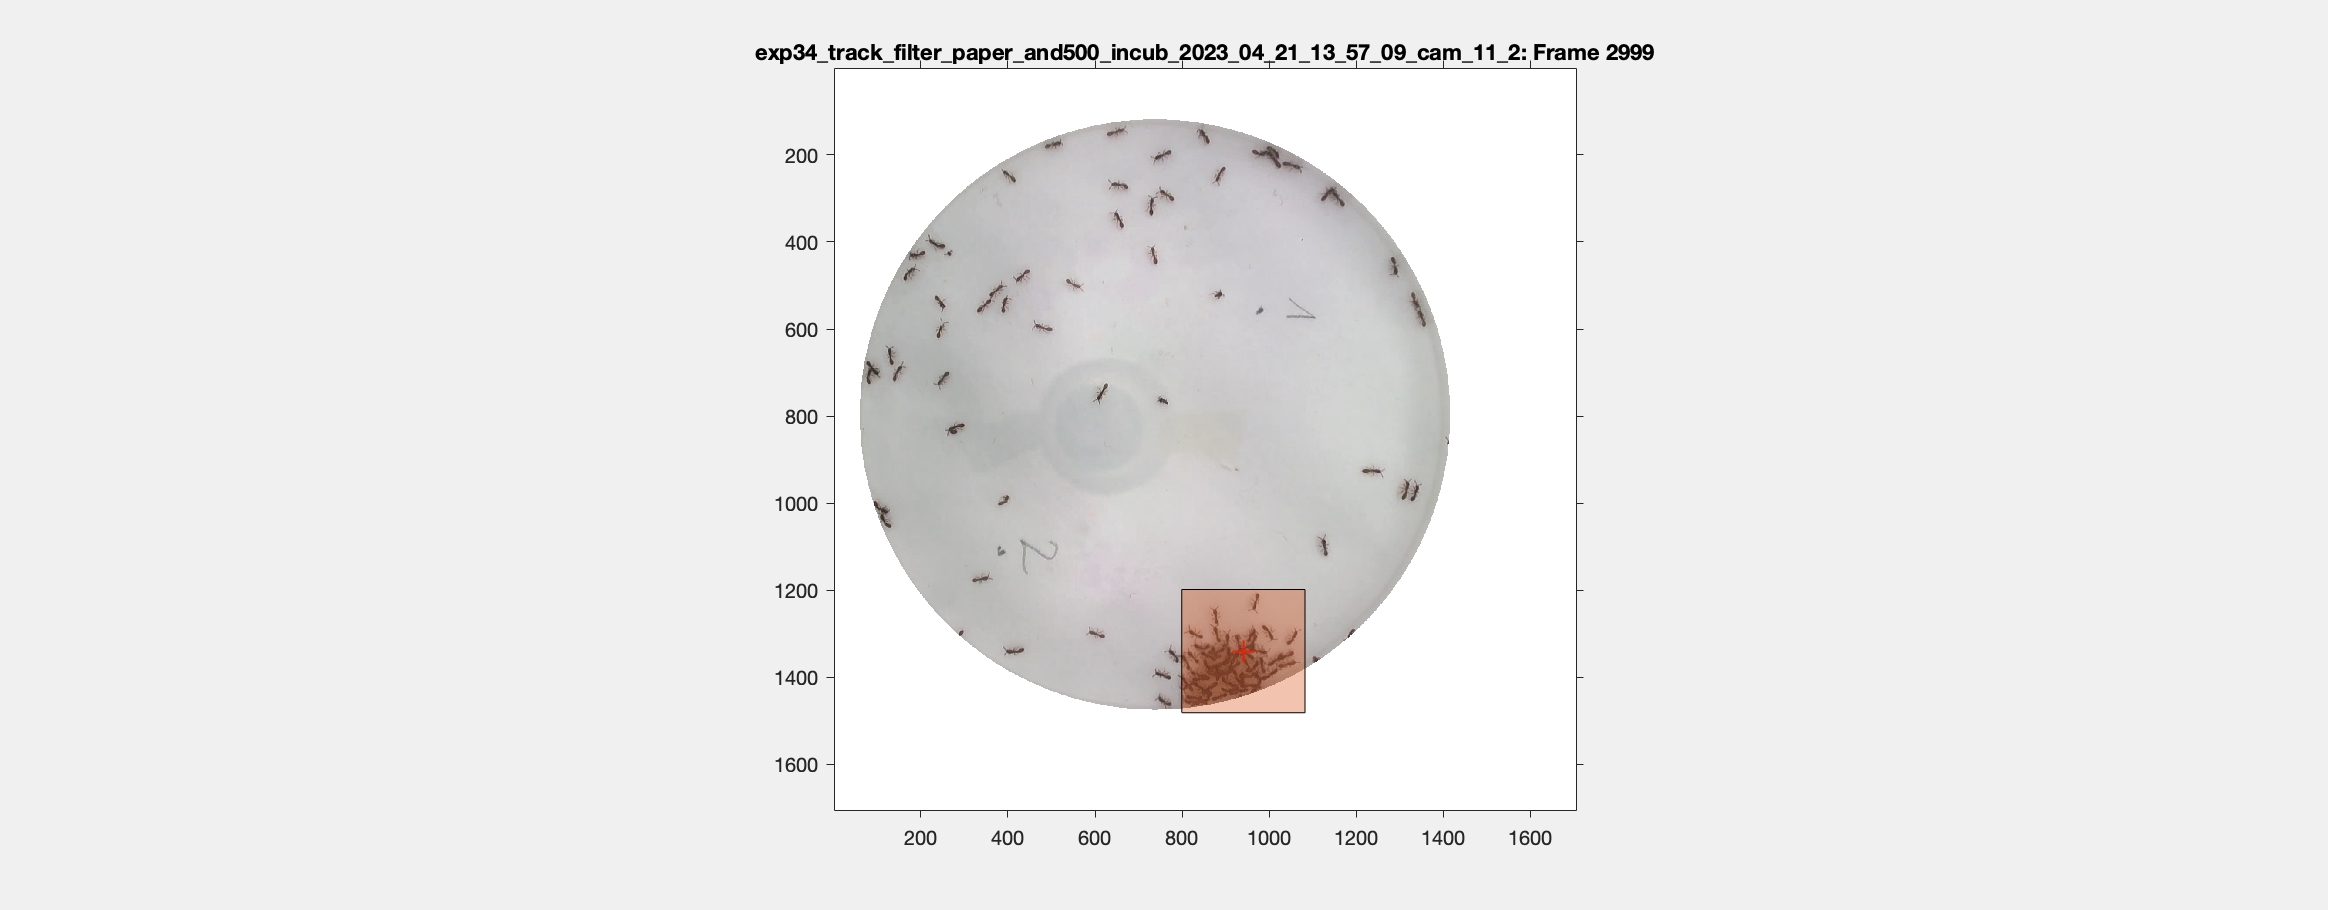

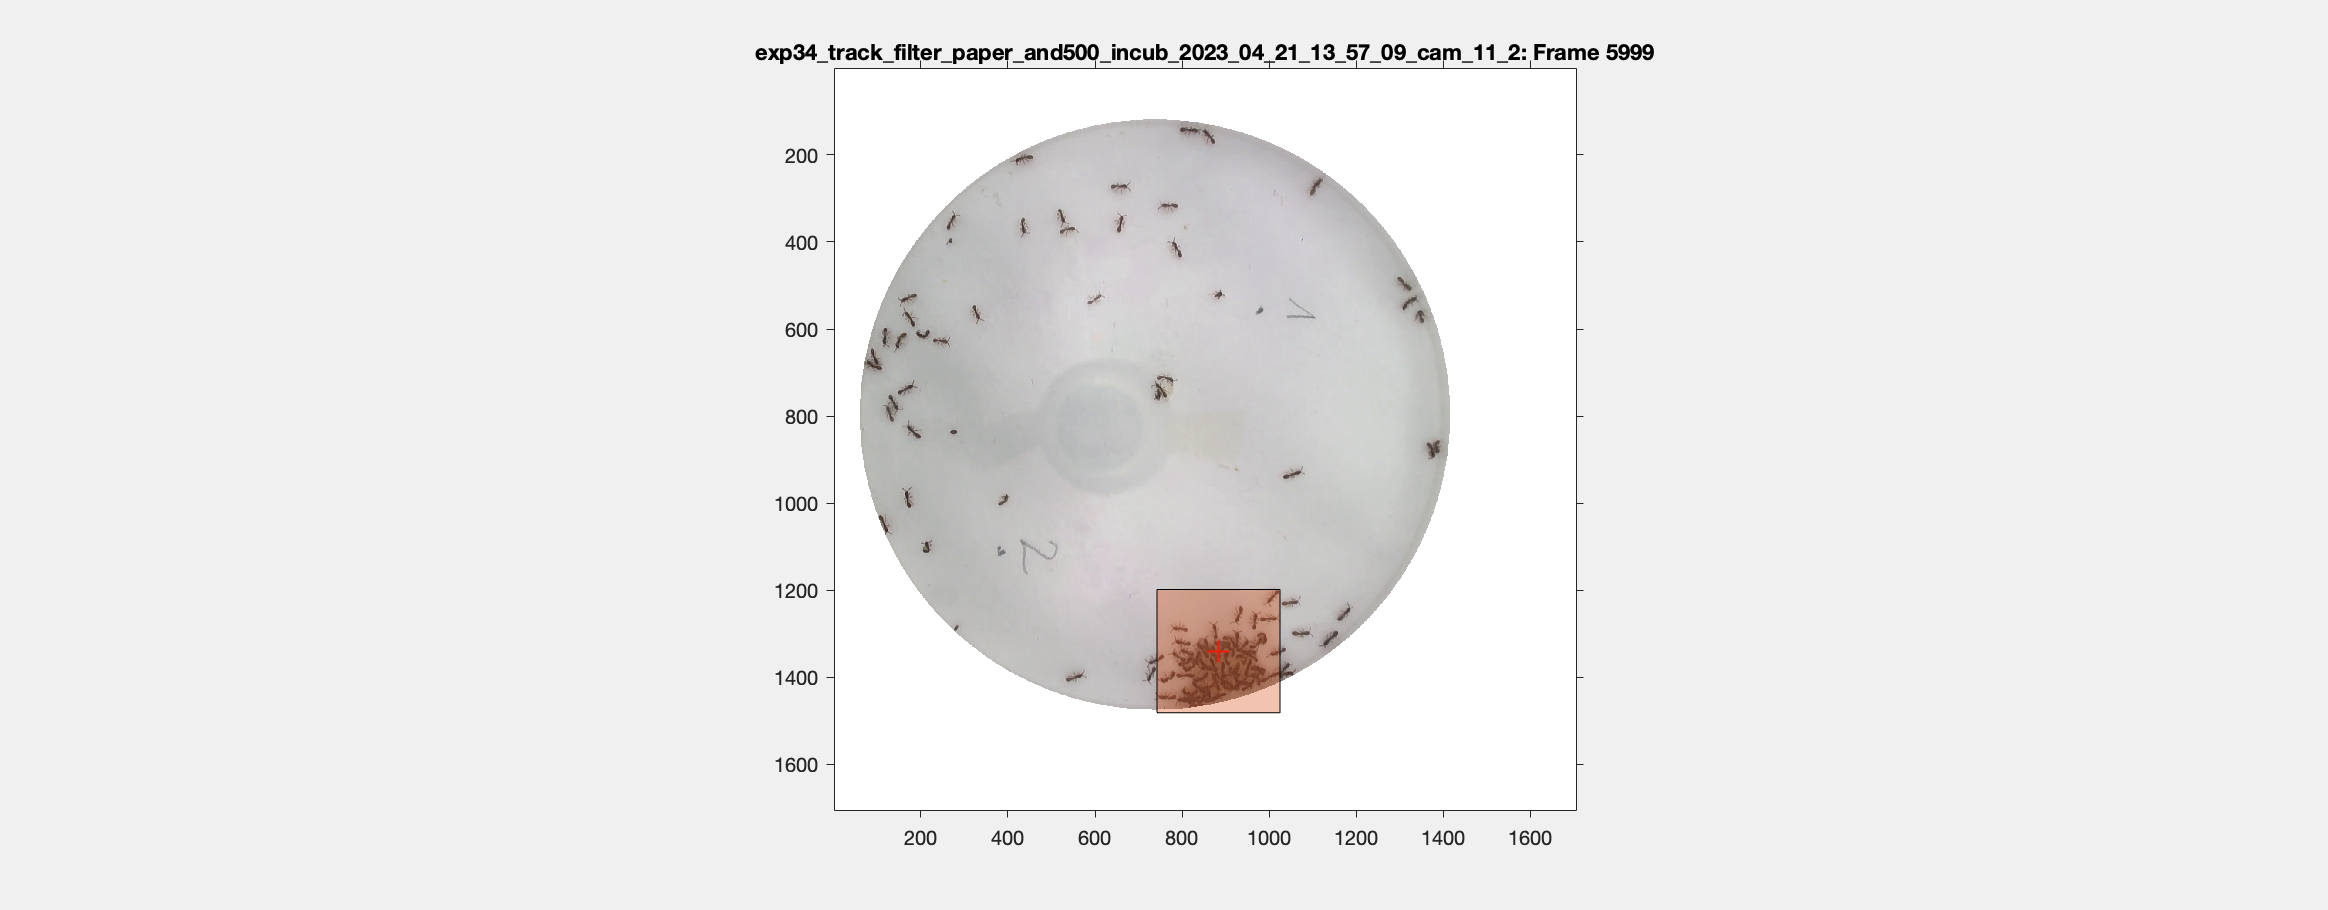

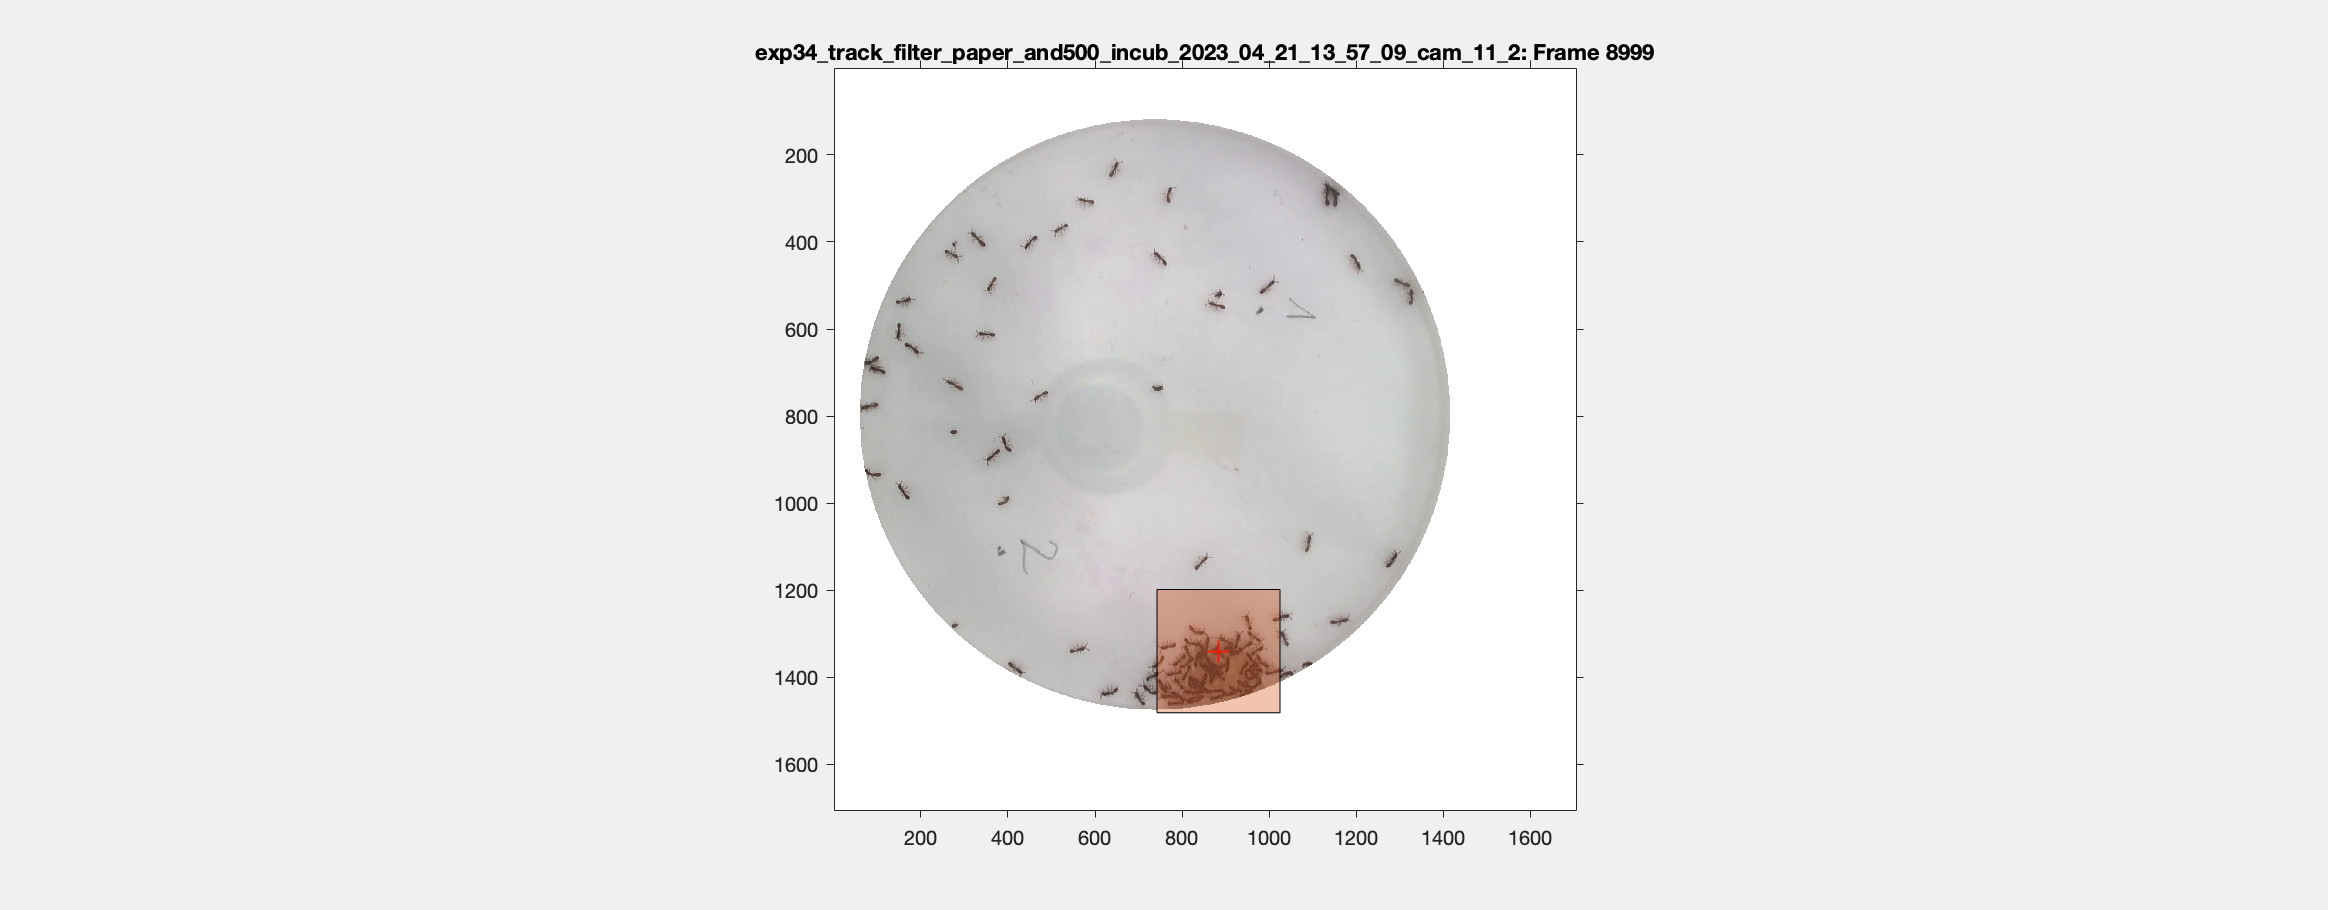



% These 3 variable will be passed to findcluster.m function
% For one-sixth of the width of the full image: tilex = round(length_x/6);
% For the whole image: size(trimmed_image, 1);
tilex = round(length_x / 6); % How many pixels will your ROI tile be?
% For one-third of the width of the roi tile: tilestep = round(tilex / 3);
tilestep = round(tilex / 5); % How many pixels do you want to pan the ROI tile per sample
% Gray threshold to detect dark objects on light background (0.5 works)
thresh = .5; % Black objects are 0.0 and white objects are 1.0

% Setting up the table 'Currtable' to capture data from findcluster.m
sizestring = 'Size';
vtypes = 'VariableTypes';
vclasses = ["datetime", "int64", "double", "double", "double"];
vnamestring = 'VariableNames';
vnames = ["date", "frame", "xpos", "ypos", "density"];
Currtable = table(...
    sizestring,[1 length(vclasses)],vtypes, vclasses, vnamestring, vnames);

% Instantiating variables to capture extra data from findcluster.m
clusters = [];
tiles = polyshape;
cluster_stack = [];


% Instantiating 3 diagnostic variables
feedingframes = 0;
framesdropped = 0;
totalframes = 0;

% Do you want the analysis loops to show general figures? [0, 1]
showfigs = 0;
% Do you want the analysis loops to show extra figures? [0, 1]
showextrafigs = 1;


tic

% To step through all images in exp_folder: i = 1:length(D)
for i = 1:length(D)
    
    frame_idx = str2double(regexp(D(i).name, '\d+', 'match'));
    
    frame = imread(D(i).name);
    frame = frame(corner_y : corner_y + length_y,...
        corner_x : corner_x + length_x, :);
    frame2 = im2gray(im2double(frame));
    frame3 = frame2 < thresh;
    
    if ~exist('bw', 'var')
        bw = drawroi(frame, 1, 0);
    end
    frame = bsxfun(@times, frame, cast(bw,class(frame)));
    
    frame_class = string(class(frame));
    if frame_class == "uint8"
            frame = bsxfun(@plus, frame, cast(~bw*255,class(frame)));
    elseif frame_class == "uint64"
            frame = bsxfun(@plus, frame, cast(~bw*intmax("uint64"),class(frame)));
    elseif frame_class == "double"
            frame = bsxfun(@plus, frame, cast(~bw,class(frame)));
    else
        disp('frame class is unresolved')
        break
    end
    
    if i == 1
        set(figure, 'WindowStyle', 'docked')
        imshow(frame, 'InitialMagnification', 'fit');
        title(strcat(basename, ": Frame ", num2str(frame_idx)), "Interpreter", 'none');
    end
    
    feedingthresh = .1 * size(frame,1) * size(frame,2);
    
    if sum(frame3, 'all') >= feedingthresh
        disp(strcat('feeding frame detected: ', num2str(frame_idx)));
        feedingframes = feedingframes + 1;
        Currtable(i,:) = {datetime(D(i).date), frame_idx, NaN, NaN, NaN};
        clusters(:,:,i) = zeros(tilex, tilex);
        cluster_stack(:,:,i) = 0;
        tiles(i) = Tile;
        continue
    end
    
    [BWimg, ROIcx, ROIcy, DCap, Tile, cluster, MMC, ~] = findcluster(frame, thresh, 1, 0, tilex, tilestep);
    
        
    if i == 1 && showfigs == 1
        set(figure,'WindowStyle','docked')
        imshow(frame, 'InitialMagnification', 'fit');
        hold on
        axis on
        plot(ROIcx, ROIcy, 'r+', 'MarkerSize', 10, 'LineWidth', 1);
        plot(Tile);
        title(strcat(basename, ": Frame ", num2str(frame_idx)), "Interpreter", 'none')
        drawnow;
    end
    
    if showextrafigs == 1 && mod(i,20) == 0
        set(figure,'WindowStyle','docked')
        imshow(frame, 'InitialMagnification', 'fit');
        hold on
        axis on
        plot(ROIcx, ROIcy, 'r+', 'MarkerSize', 10, 'LineWidth', 1);
        plot(Tile);
        title(strcat(basename, ": Frame ", num2str(frame_idx)), "Interpreter", 'none')
        drawnow;
    end
    
    if ~isnan(ROIcx) && ~isnan(ROIcy)
        Currtable(i,:) = {datetime(D(i).date), frame_idx, ROIcx, ROIcy, DCap};
        clusters(:,:,i) = cluster;
        cluster_stack(:,:,i) = MMC;
        tiles(i) = Tile;
        totalframes = totalframes + 1;
    else
        Currtable(i,:) = {datetime(D(i).date), frame_idx, NaN, NaN, NaN};
        clusters(:,:,i) = zeros(tilex, tilex);
        cluster_stack(:,:,i) = 0;
        tiles(i) = Tile;
        disp(strcat("ROI nan detected: i = ", num2str(frame_idx)));
        framesdropped = framesdropped + 1;
    end
end


BW = bw;
clear bw;
cluster_heatmap = sum(cluster_stack, 3);

%%

framescounted = i;
disp(strcat("Folder: ", basename));

Folder: exp34_track_filter_paper_and500_incub_2023_04_21_13_57_09_cam_11_2


disp(strcat("frames counted: ", num2str(framescounted)));

frames counted: 60


disp(strcat("frames dropped: ", num2str(framesdropped), " (",...
    num2str(framesdropped / (framescounted)), ")"));

frames dropped: 0 (0)


disp(strcat("frames no tray: ", num2str(feedingframes), " (",...
    num2str(feedingframes / (framescounted)), ")"));

frames no tray: 0 (0)


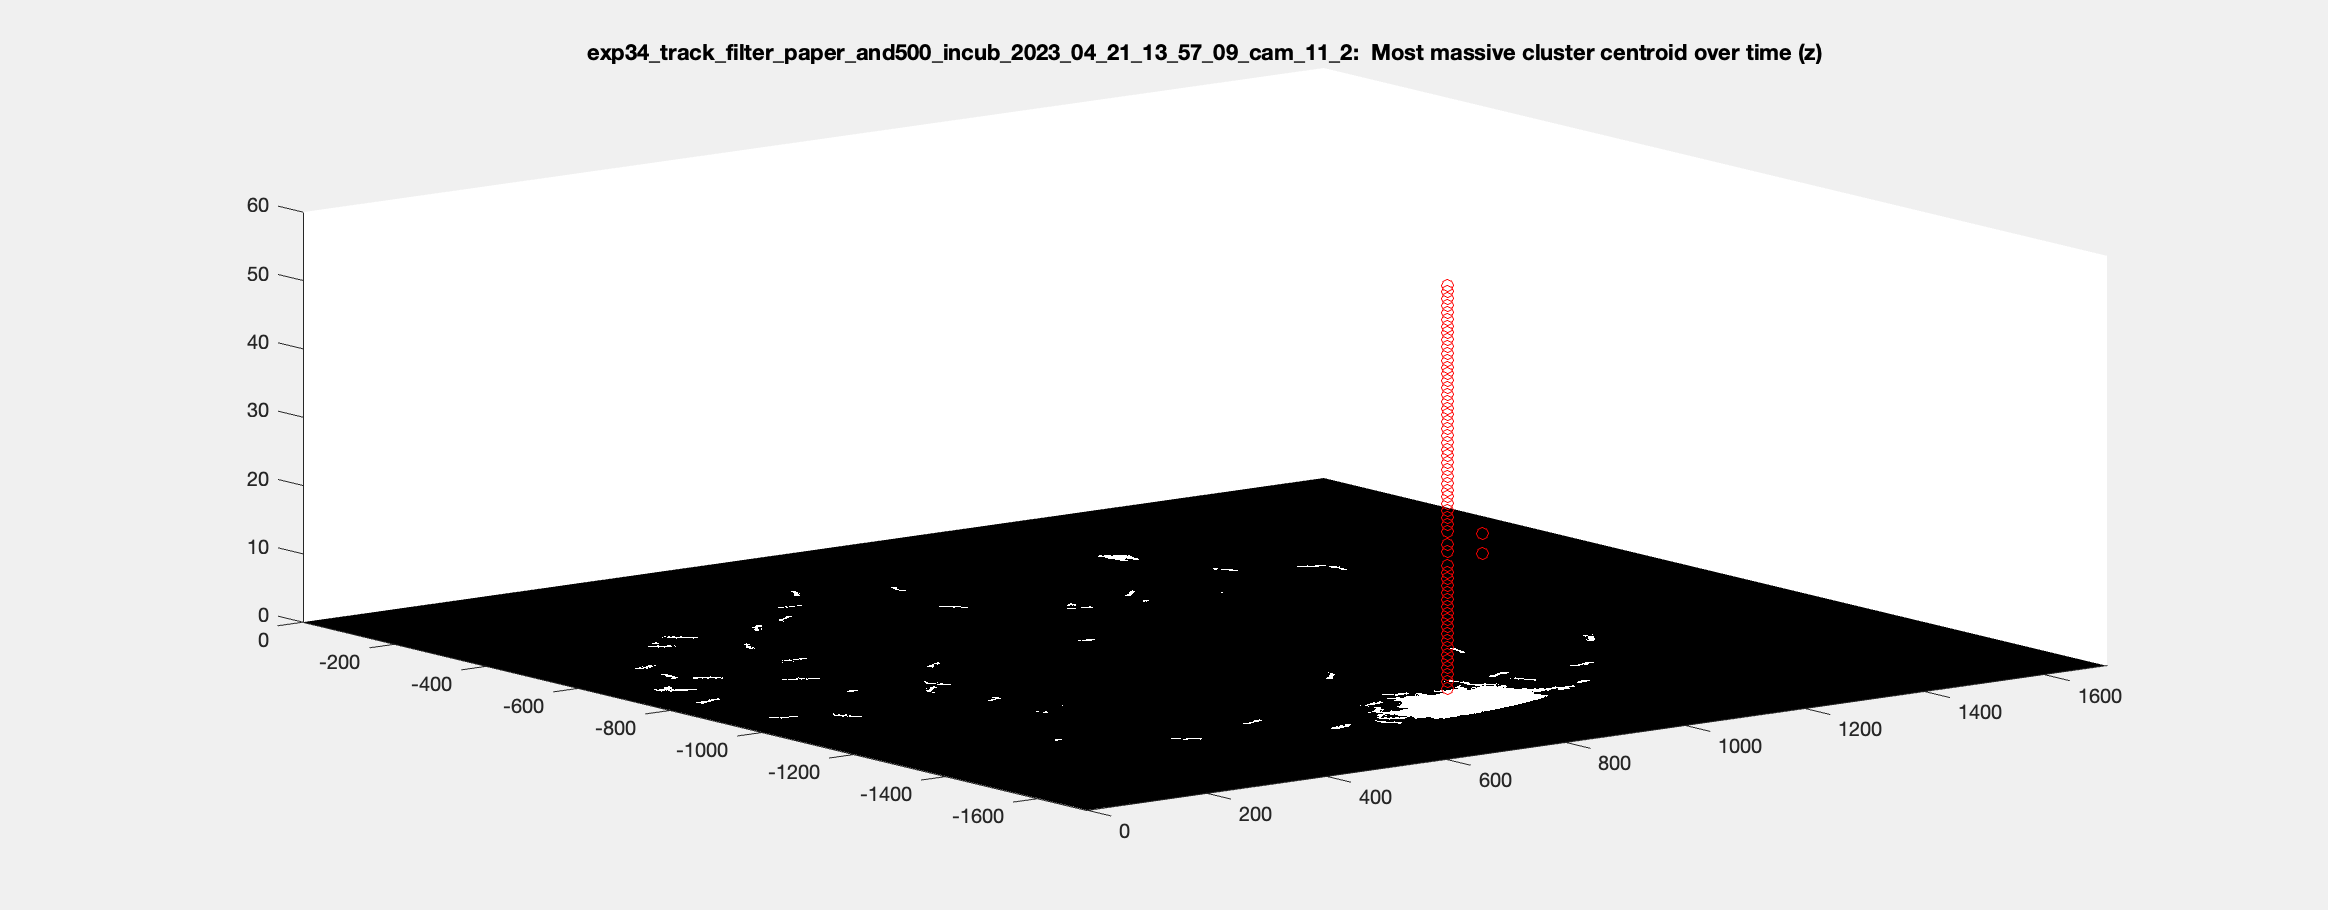

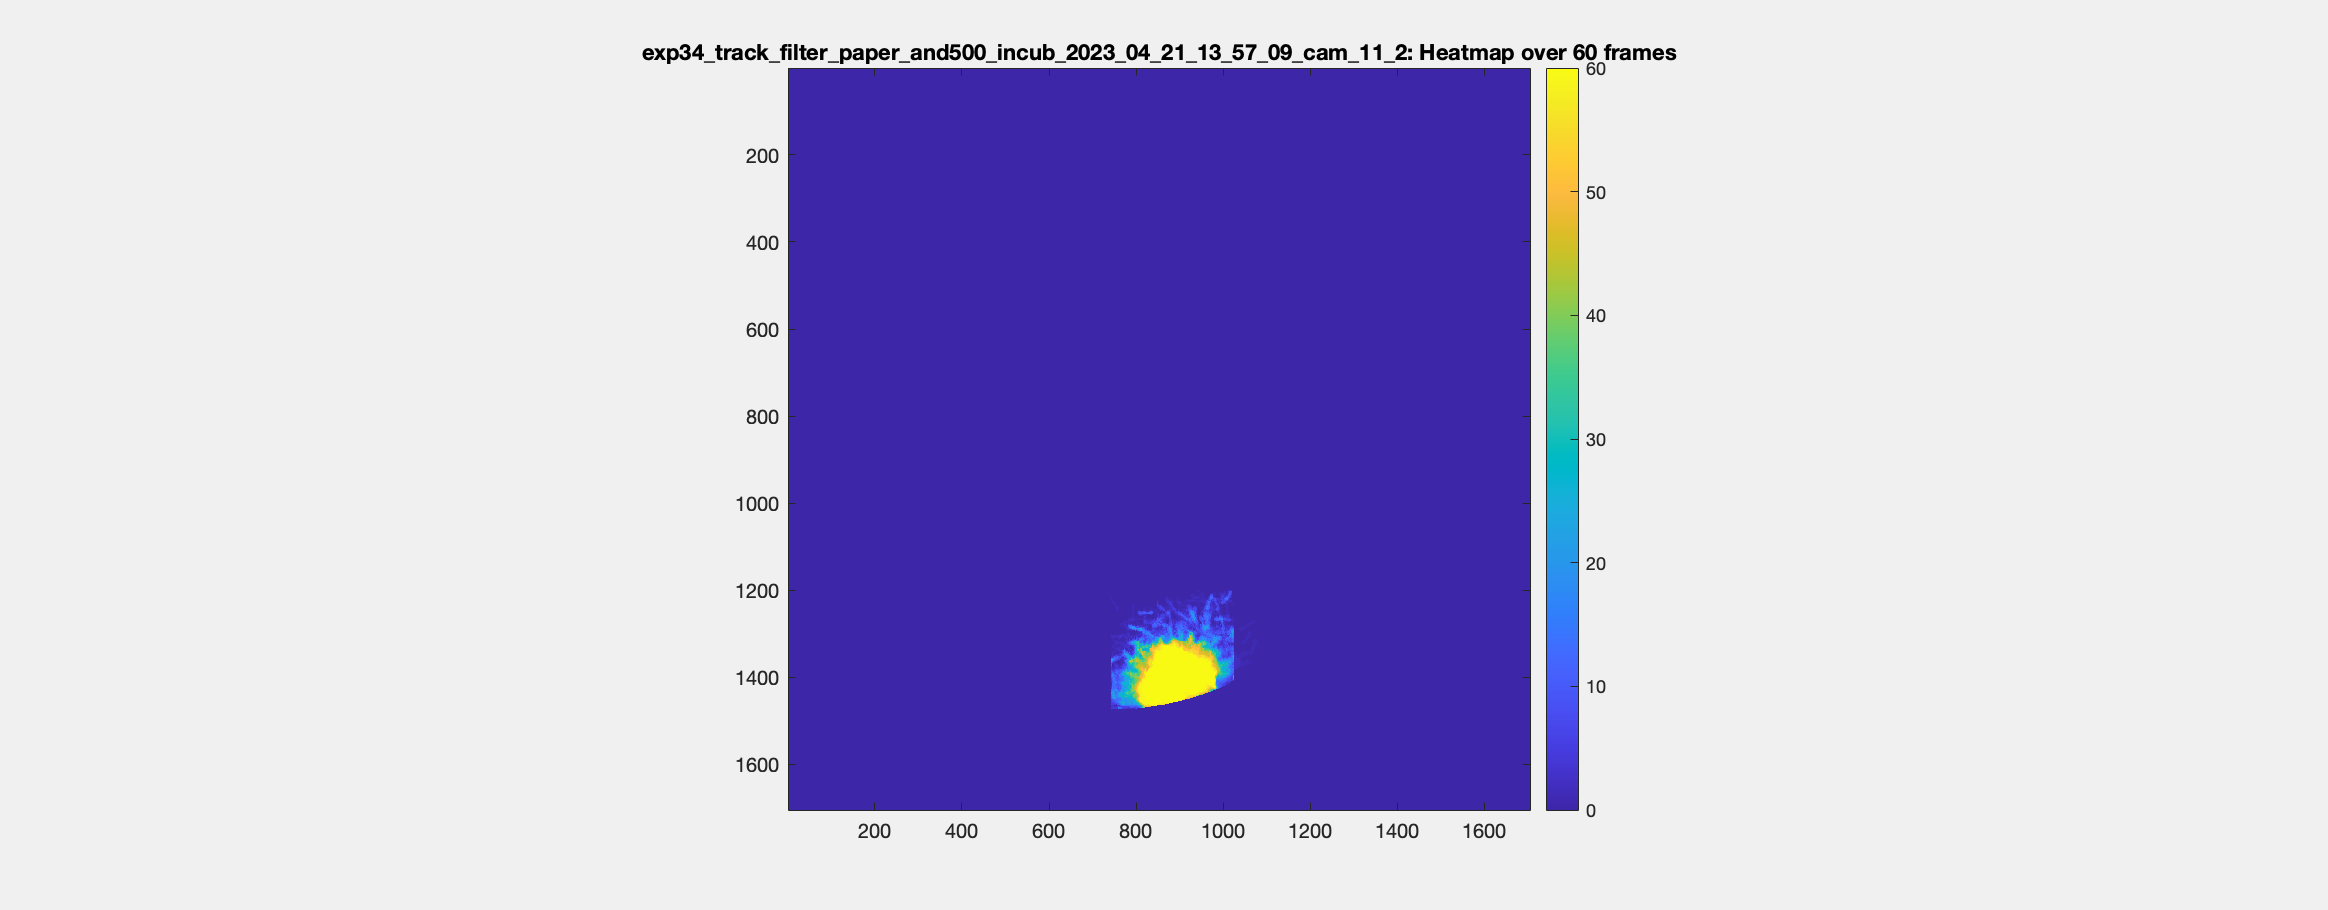


if showextrafigs == 1
    set(figure,'WindowStyle','Docked')
    plot3(Currtable.xpos,-Currtable.ypos,1:height(Currtable),'ro')
    hold on
    xlim([0 size(frame3,2)])
    ylim([-size(frame3,1) 0])
    colormap(gray);
    z_off = 0;
    X = [1 size(frame3,2)];
    Y = [1 -size(frame3,1)];
    Z = z_off + zeros(2);
    surf(X,Y,Z, im2double(BWimg),'FaceColor','texturemap','EdgeColor','none')
    title(strcat(basename, ":  Most massive cluster centroid over time (z)"), "Interpreter", 'none');
    drawnow;
    
    set(figure,'WindowStyle','Docked')
    imagesc(cluster_heatmap)
    colorbar
    title(strcat(basename, ": Heatmap over ", num2str(totalframes), " frames"), "Interpreter", 'none')
    axis image
end

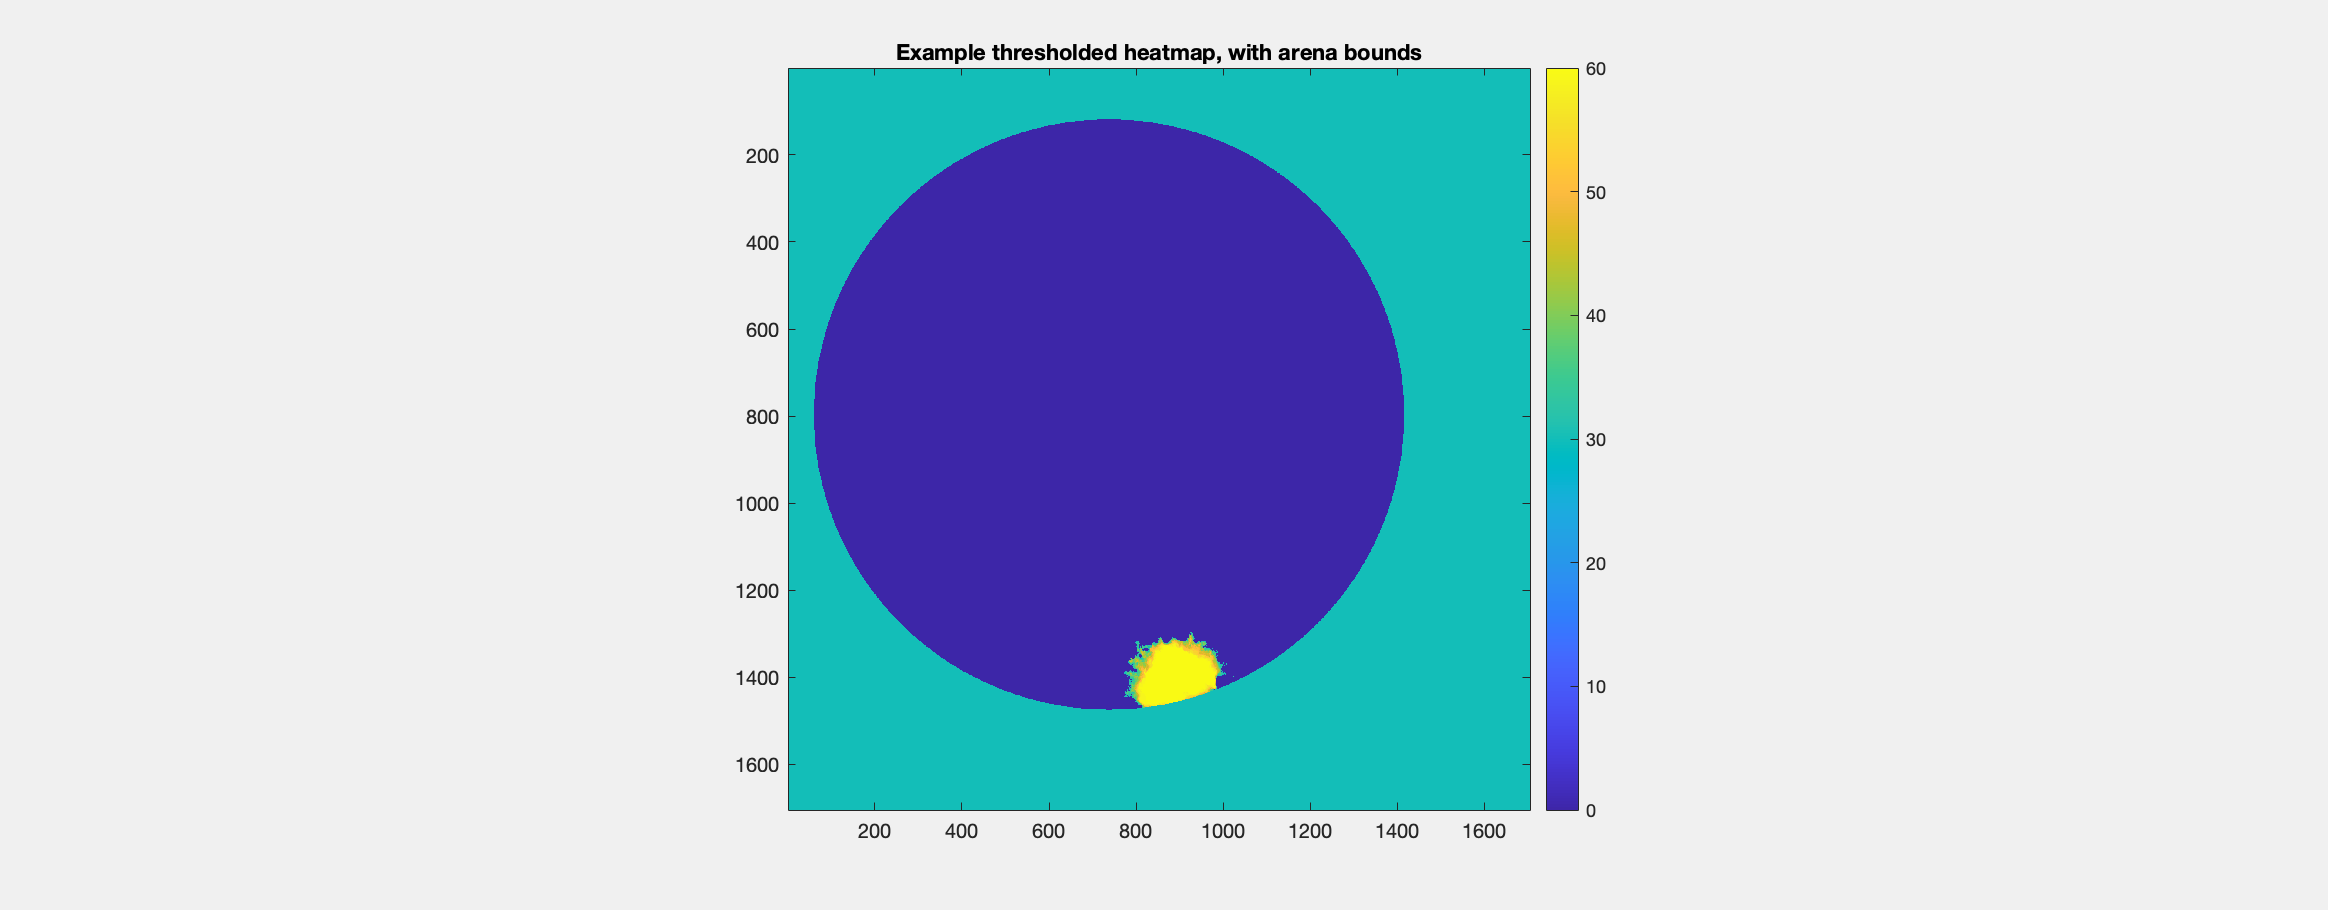



test = cluster_heatmap;
test(test < max(test, [], 'all')/2) = 0;
set(figure, 'WindowStyle', 'Docked')
imagesc(test + (~BW .* max(test,[], 'all')/2))
% imagesc(test > max(test, [], 'all')/2); % logically threshold
% imshow(cluster_stack(:,:,35);
title('Example thresholded heatmap, with arena bounds')
axis image
% colormap('Winter')
colorbar


warningState = warning('off', 'MATLAB:MKDIR:DirectoryExists');
data_folder = mkdir(exp_folder, 'data');
warning(warningState);
cd(strcat(exp_folder,"/data"));
F = sprintf('%s.mat', basename);
save(F, 'Currtable');
save workspace;
cd(exp_folder)

toc

Elapsed time is 41.767623 seconds.




%get centroid #average #and rotate
%NEED TO HAVE REALYY CONSISTENLTY CENTERED ROI
Stats=regionprops(BW)

Stats = struct with fields:
           Area: 1443038
       Centroid: [737.7617 796.1953]
    BoundingBox: [59.5000 118.5000 1356 1356]


centroid=Stats.Centroid

centroid =   737.7617  796.1953


Relative_xy= [ROIcx ROIcy] - centroid

Relative_xy =   145.7383  543.3047


%rotate90= @(x,y) [-y,x]
%the above should be counterclockwise
%if more transfers in same arena/more rotations: rotate180= @(x,y) [-x,-y] , rotate270= @(x,y) [y,-x] 


%--------------------------------------------------------------------------
% To load your experimental workspace: 
%     cd(strcat(exp_folder,"\data"));
%     load('workspace.mat')
% To load specific variables:
%     load('workspace.mat', 'cluster_heatmap', 'Currtable')
% To prevent overwriting current variables:
%     Experiment1_heatmap = load('workspace.mat', 'cluster_heatmap');
%     or
%     Heatmaps(i) = load('workspace.mat', 'cluster_heatmap');
%--------------------------------------------------------------------------
% Thank you for using cLusterTrax!
% Please cite:
% Dennis O. Melendez, cLusterTrax v. 1.0 (2023)
%--------------------------------------------------------------------------
